# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 2022-06-06 16:33:57

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ["\t", ","];

% Specify column names and types
opts.VariableNames = ["Freq", "abs_Z__open", "arg_Z__open", "abs_Z__short", "arg_Z__short"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["abs_Z__open", "arg_Z__open", "abs_Z__short", "arg_Z__short"], "TrimNonNumeric", true);
opts = setvaropts(opts, ["abs_Z__open", "arg_Z__open", "abs_Z__short", "arg_Z__short"], "ThousandsSeparator", ",");

% Import the data
tbl = readtable("AC -220627 - Compressor (Half-yearly meeting).txt", opts);

## Convert to output type

Freq = tbl.Freq;
abs_Z__open = 10.^(tbl.abs_Z__open/20);
arg_Z__open = tbl.arg_Z__open;
abs_Z__short = 10.^(tbl.abs_Z__short/20);
arg_Z__short = tbl.arg_Z__short;

## Clear temporary variables

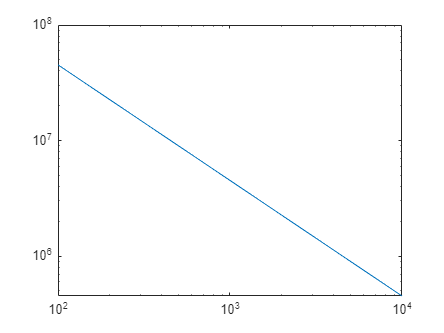

clear opts tbl

loglog(Freq,abs_Z__open);
hold on
loglog(Freq,arg_Z__open);
hold off

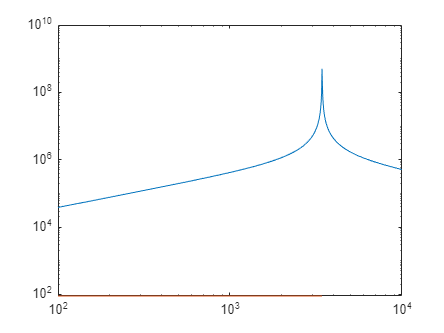


loglog(Freq,abs_Z__short);
hold on
loglog(Freq,arg_Z__short);
hold off


D = [Freq, abs_Z__open, arg_Z__open, abs_Z__short, arg_Z__short];
save 'AC -220627 - Compressor (Half-yearly meeting)_.txt' D -ascii
